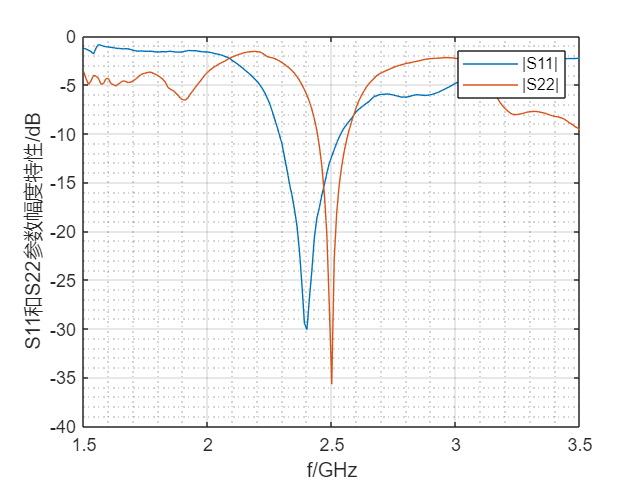

clear;clc;
%%%%%%%%%%%%%%%%%%%绘制图像%%%%%%%%%%%%%%%%%%%
load newdata8;
f=newdata8(:,1);
S11=10.^(newdata8(:,2)./20).*(exp(pi/180*1i*(newdata8(:,3))));
S21=10.^(newdata8(:,4)./20).*(exp(pi/180*1i.*(newdata8(:,5))));
S12=10.^(newdata8(:,6)./20).*(exp(pi/180*1i.*(newdata8(:,7))));
S22=10.^(newdata8(:,8)./20).*(exp(pi/180*1i.*(newdata8(:,9))));
Z=50*(1+S11)./(1-S11);
Z2=50*(1+S22)./(1-S22);
%%%%%%%%%%%%%%%%%%%绘制图像%%%%%%%%%%%%%%%%%%%
figure();
plot(f/1e9,20*log10(abs(S11)));
hold on;
plot(f/1e9,20*log10(abs(S22)));
xlabel('f/GHz');
ylabel('S11和S22参数幅度特性/dB');
legend("|S11|","|S22|");
grid on;grid minor;

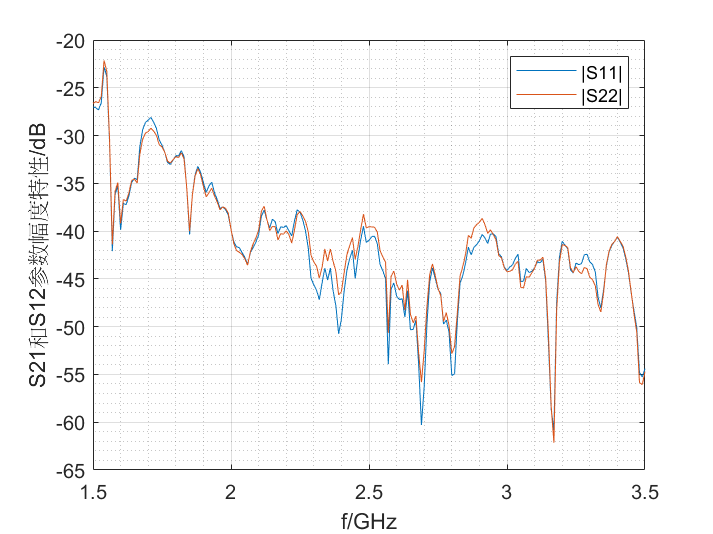


figure();
plot(f/1e9,20*log10(abs(S21)));
hold on;
plot(f/1e9,20*log10(abs(S12)));
xlabel('f/GHz');
ylabel('S21和S12参数幅度特性/dB');
legend("|S11|","|S22|");
grid on;grid minor;

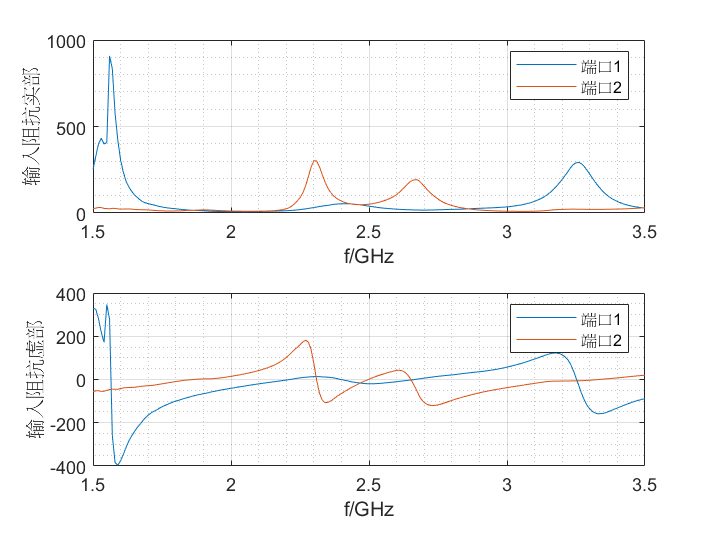


figure();
subplot(2,1,1);
plot(f/1e9,real(Z));
hold on;
plot(f/1e9,real(Z2));
xlabel('f/GHz');
ylabel('输入阻抗实部');
legend("端口1","端口2");
grid on;grid minor;
subplot(2,1,2);
plot(f/1e9,imag(Z));
hold on;
plot(f/1e9,imag(Z2));
xlabel('f/GHz');
ylabel('输入阻抗虚部');
legend("端口1","端口2");
grid on;grid minor;